ARN_st.name='ARN';
ARN_st.lat=37.1;
ARN_st.lon=-6.7333;
ARN_st.alt=41;


ARN_rd=read_betsy('ARN_2005_2018');

a =    1.0e+03 *
    1.1670    1.1670    1.2438    1.2793    1.2793    1.3929    0.1272    0.1272    0.1272    0.1273    0.1273    0.1273    0.1517    0.1517    0.1517    0.2727    0.2727    0.2727    0.2727    0.2727    0.2727    0.3112    0.3112    0.3112

datevec(ARN_rd.Time(1))

ans =         2006           1           1           0           0           0

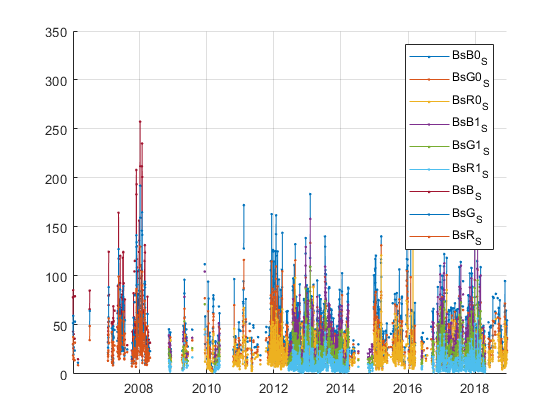

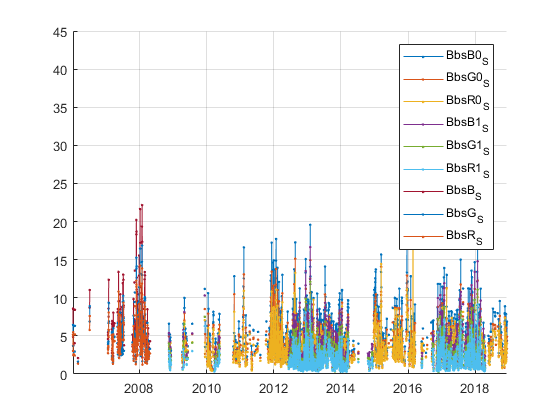

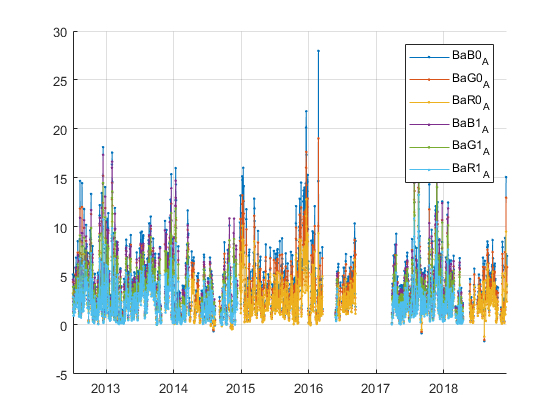

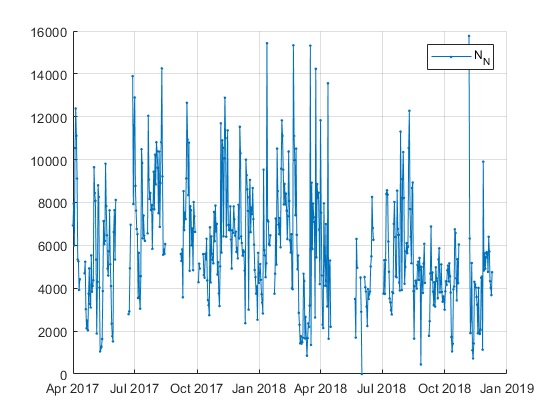

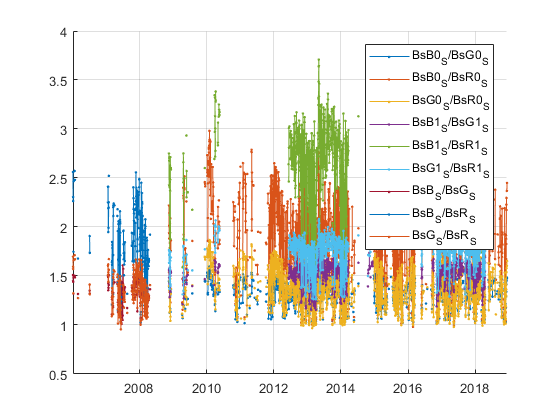

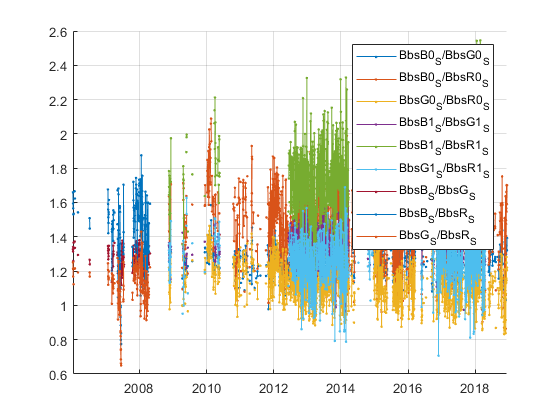

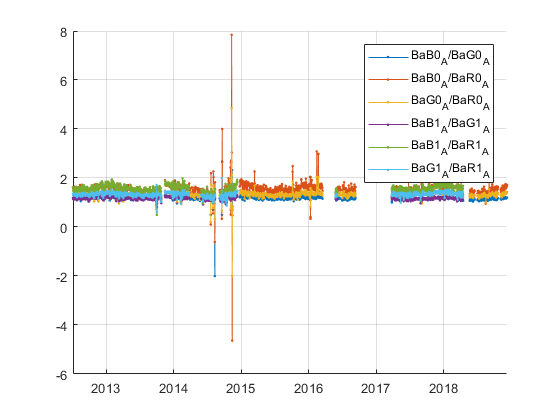

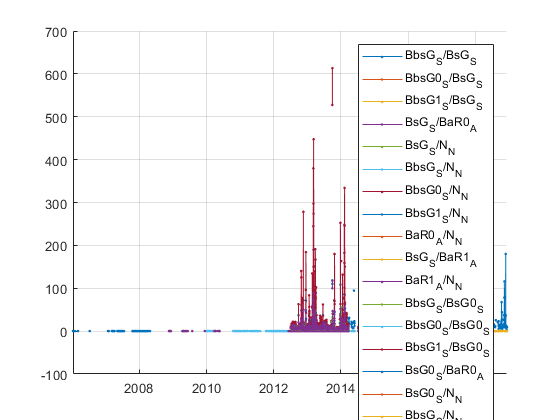

plotFigControl(ARN_rd);

% 2 size cut, ok but with low coverage for PM1: not usable
% sc: ok, no clear seasonal cycle, no negatives
% abs:no clear seasonal cycle, few negatives


%N only since april 2017: not usable

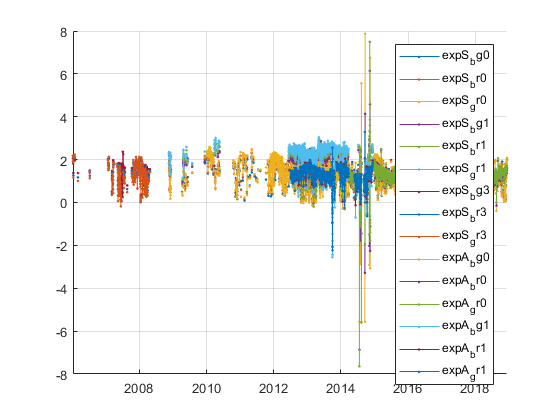

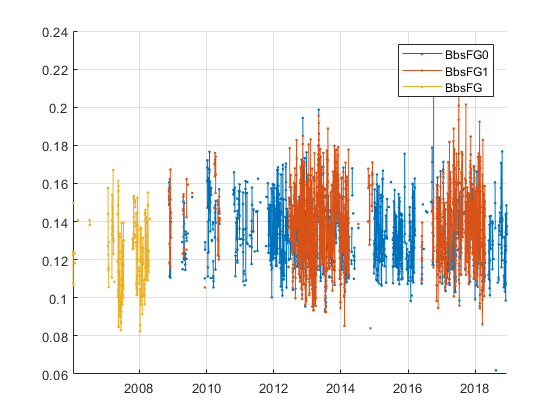

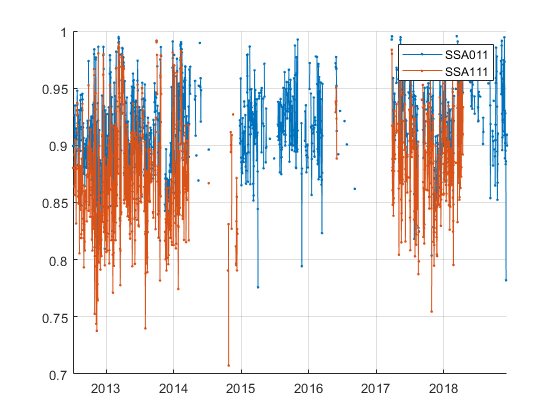

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;529;653]*ones(1,4);
ARN_cal=compute_exp_SSA(ARN_rd,lambdaSC, lambdaAE);
plotFigControl_cal(ARN_cal);

%Questions:
%problems:
% PM1 has too low coverage: trend  analysis not possible
% 2006: too low data coverage
% 2007-2008: seems to be TSP, minima > minima PM 10: rupture probable
%PM10 data: too low data coverage in 2009 and in 2010
% rupture clearly visible at the beginning of March 2012 in Bbs ratio with R, not so clear in scat and not in BG ratio

%Abs: PM1: no data in 2015 and 2016 ??
%abs: PM10 can be use, begin in 2012
% abs ratio: rupture probable in January 2015: what happens ??

%expSC seems to be more homogen between TSp and PM10: usable ?? it seems however to be too high in 2010-2012.


ARN_t=timetable(ARN_rd.Time);
%scat  begin at the beginning of a year: 2012, too low data coverage before
% neph and abs PM1 to remove
%remove N